% Just loading up the values that SEEM like theyre correct.
load('sim_data_single.mat')
c = 3e8; % m/s

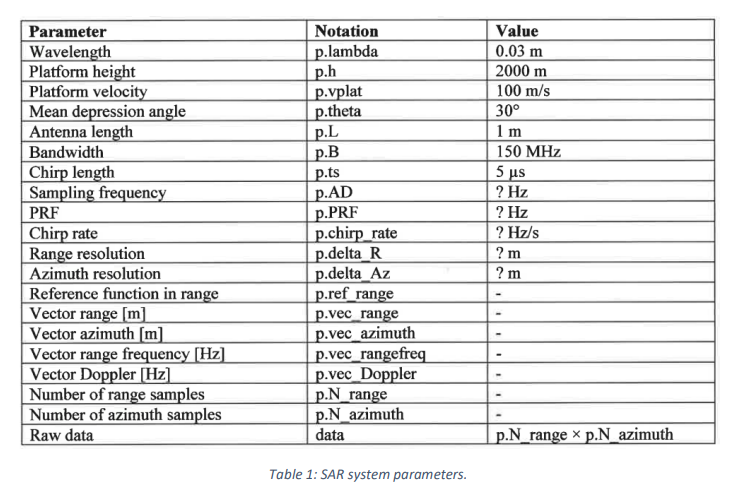

# Question 1 - SAR Signal Simulator

1) Determine the sampling frequency to avoid range ambiguities and the PRF to avoid azimuth ambiguities due to sub-sampling. Give theoretical resolutions in range and azimuth (hint: use IQ sampling)

base_frequency = c/p.lambda % Around 10 GHz

base_frequency = 1.0000e+10

The range is determined by the angle of the beam plus half its width along the ground. (Recall Tristyn's drawings)

p.h % Height above ground

ans = 2000

p.theta % Mean depression angle (down from flat to where being illuminated)

ans = 0.5236

beam_centre_length = p.h / sin(p.theta)

beam_centre_length = 4.0000e+03


% max_range = find length plus width thing and then take that shit and find
% the hypoteneus of it

Max unambiguous range is $R_{max} = \frac{c}{2 \cdot PRF} = \frac{c \cdot PRI}{2}$, and recall that $\Delta R = \frac{c}{2B}$

% So
PRF_min = c / (2 * max_range) % Increasing Rmax means decreasing PRF

Unrecognized function or variable 'max_range'.

p.delta_R = c/(2*p.B)


% azimuth resolution is apparently 1/length of antenna?
% Range resolution = fixed
% PRF gives us max range (unambiguous)
% PRF gives max measurable doppler ĸ